# Text Analysis of MATLAB Subreddit

*Created with R2022b. Compatible with R2021b and later releases*

I wrote a custom function that parses posts from a subreddit, and here is an example of how to use it, if you are interested.

The function gets data from Reddit RSS feed instead of API, so that we don't have to deal with OAuth.

## Load data from Reddit

First, let's get the posts from MATLAB subreddit, using "hot" sortby option. Other options include new, top, rising, etc. This returns a nested structure array.

s = getReddit(subreddit='matlab',sortby='hot',limit=100,max_requests=1);

Since default input values are set in the function, you can just call getReddit() without input arguments if the default is what you need.

## Extract text

Now let's extract text from fields of interest and organize them as columns in a table array T.


T = table;
T.Subreddit = arrayfun(@(x) string(x.data.subreddit),s);
T.Flair = arrayfun(@(x) x.data.link_flair_text, s, UniformOutput=false);
T.Title = arrayfun(@(x) string(x.data.title), s);
T.Body = arrayfun(@(x) string(x.data.selftext), s);
T.Author = arrayfun(@(x) string(x.data.author), s);
T.Created_UTC = datetime(arrayfun(@(x) x.data.created_utc, s), "ConvertFrom","epochtime");
T.Permalink = arrayfun(@(x) string(x.data.permalink), s);
T.Ups = arrayfun(@(x) x.data.ups, s);
T = table2timetable(T,"RowTimes","Created_UTC");

## Remove pinned posts

isPinned = year(T.Created_UTC) < 2023;
T(isPinned,:) = [];

## Get daily summary

Summarize the number of tweets by day and visualize it.

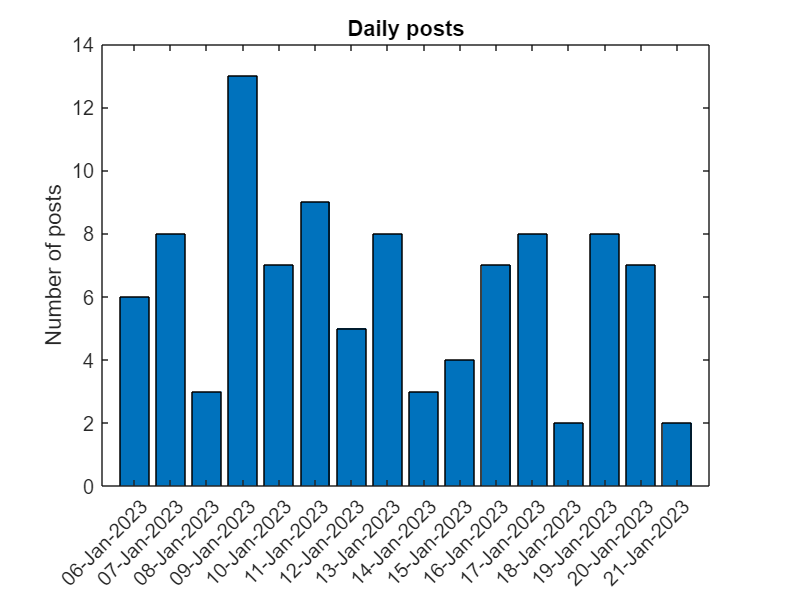

% Compute group summary 
dailyCount = groupsummary(T,"Created_UTC","day");
figure
bar(dailyCount.day_Created_UTC,dailyCount.GroupCount)
ylabel('Number of posts') 
title('Daily posts') 

## Preprocess the text data

Use lower case

T.Title = lower(T.Title);
T.Body = lower(T.Body);

Replace blank space char

T.Title = decodeHTMLEntities(T.Title);
T.Title = replace(T.Title,"​"," ");
T.Body = decodeHTMLEntities(T.Body);
T.Body = replace(T.Body,"​"," ");

Remove URLs

T.Body = eraseURLs(T.Body);

Remove code

T.Body = eraseBetween(T.Body,"`","`","Boundaries","inclusive");
T.Body = eraseBetween(T.Body,"    ",newline,"Boundaries","inclusive");

Remove tables

tblels = asManyOfPattern(alphanumericsPattern(1) | characterListPattern("[]\*:- "),1);
tbls = asManyOfPattern("|" + tblels) + "|" + optionalPattern(newline);
T.Body = replace(T.Body,tbls,'');

Remove some verbose text from Java

T.Body = eraseBetween(T.Body,'java.lang.',newline,'Boundaries','inclusive');
T.Body = eraseBetween(T.Body,'at com.mathworks.',newline,'Boundaries','inclusive');
T.Body = eraseBetween(T.Body,'at java.awt.',newline,'Boundaries','inclusive');
T.Body = eraseBetween(T.Body,'at java.security.',newline,'Boundaries','inclusive');

## Tokenize the text data

Combine the title and body text and turn it into tokenized documents and do some more clean-ups.

docs = T.Title + ' ' + T.Body;
docs = tokenizedDocument(docs,'CustomTokens',{'c++','c#','notepad++'});
docs = removeStopWords(docs);
docs = replace(docs,digitsPattern,"");
docs = erasePunctuation(docs);
docs = removeWords(docs,"(:");

## Create bag of words

Use the tokenized documents to generate a bag of words model using bigrams.

bag = bagOfNgrams(docs,"NgramLengths",2);

## Visualize with word cloud

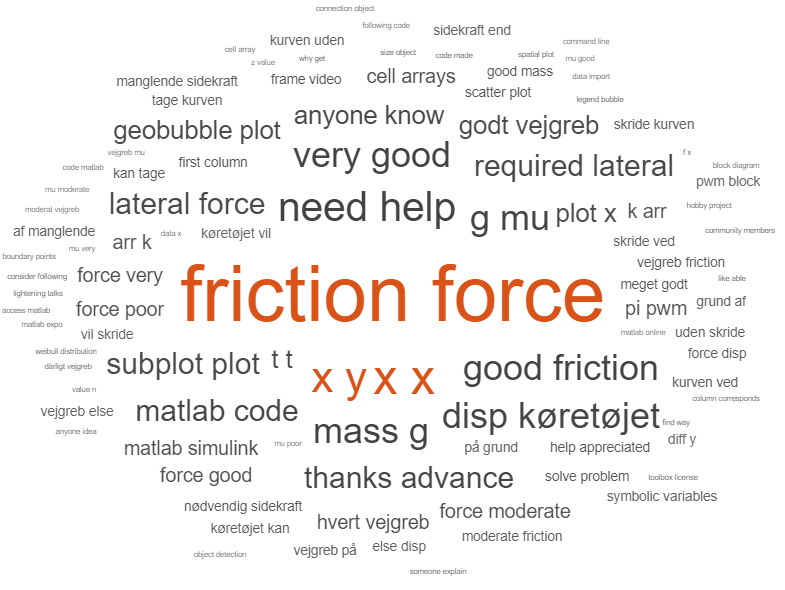

figure
wordcloud(bag);

*Copyright 2023 The MathWorks, Inc.*